# Trajectory

load("traj.mat")
%full_path = remove_duplicates(full_path);

%full_path(13:24,2) = full_path(24:-1:13,13)
%full_path(13:24,13) = tmp;

d1 = full_path(:,1:7);
d2 = full_path(:,[1,8:13]);
d3 = full_path(:,[1,14:19]);

collisions = sum(sum(((d1(:,2:4)-d2(:,2:4)).^2),2)<.1^2) + sum(sum(((d1(:,2:4)-d3(:,2:4)).^2),2)<.1^2) + sum(sum(((d2(:,2:4)-d3(:,2:4)).^2),2)<.1^2) 

collisions = 0

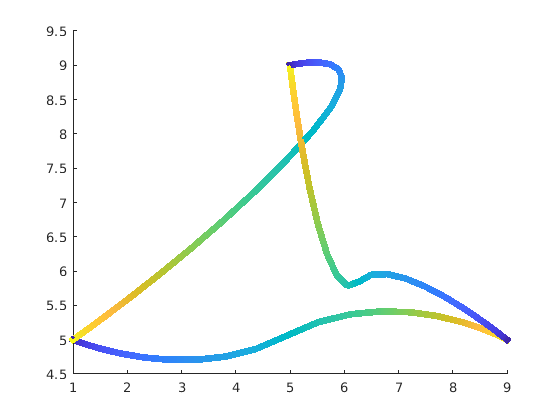


figure(1)
clf
patch([d1(:,2);nan],[d1(:,3);nan],[d1(:,4);nan],[d1(:,1)/max(d1(:,1));nan],'EdgeColor','interp','FaceColor','none','LineWidth',5);
hold on;
patch([d2(:,2);nan],[d2(:,3);nan],[d2(:,4);nan],[d2(:,1)/max(d2(:,1));nan],'EdgeColor','interp','FaceColor','none','LineWidth',5)
hold on;
patch([d3(:,2);nan],[d3(:,3);nan],[d3(:,4);nan],[d3(:,1)/max(d3(:,1));nan],'EdgeColor','interp','FaceColor','none','LineWidth',5)

# Costs

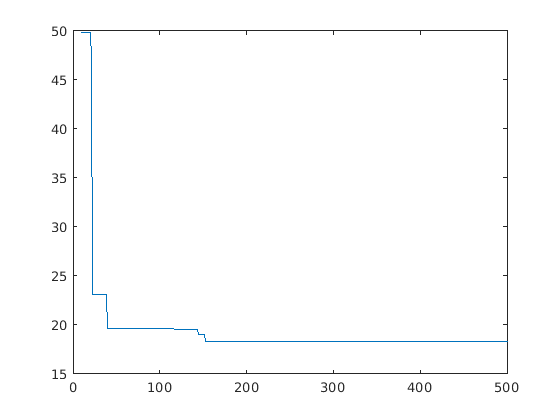

load("cost.mat")
figure(2)
plot(iteration_costs(:,1),iteration_costs(:,2))

# Time

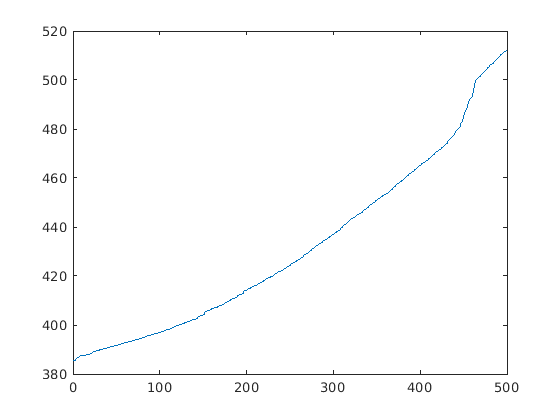

load("times.mat")
figure(3)
plot(iteration_times(:,1),iteration_times(:,2))